Paremeters

N = 100000;
n = 100000;
seed = 27;

rng(seed, "v5uniform")

function  [p_n] = run_sim(n, N)
bday_same_count = 0;

for N_idx = [1 : N]
    x = randi([1, 365], n,1);
    if (numel(unique(x)) < n)
        bday_same_count = bday_same_count + 1;
    end
end

p_n = bday_same_count/N;
% ci = [1.96 +  1.96 -]
end

a.) p_10

% end
run_sim(10, 10)

ans = 0

b.) p_20

run_sim(20, 20)

ans = 0.2500

c.) p_30

run_sim(30, 30)

ans = 0.7333

d.)

N = 10000;
n_max = 50;

p = zeros(n_max,1);
ns = [1 : n_max]';
for n = [1 : n_max]
    p(n) = run_sim(n, N);
end


intersection = [find(abs(p - 0.5) <= (0.01)), 0.5]

intersection =    23.0000    0.5000


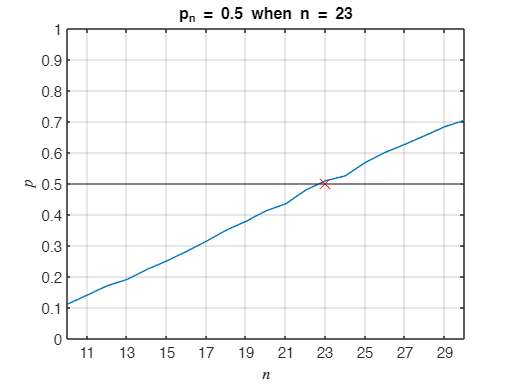


title('p_n = 0.5 when n = 23')

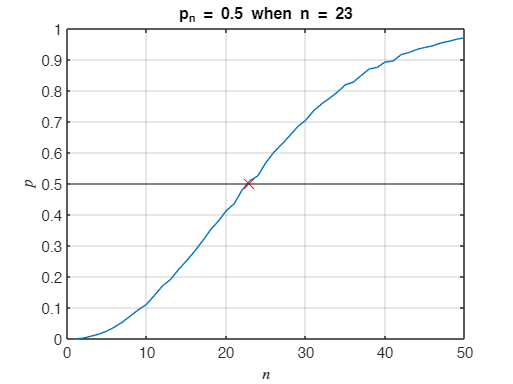

plot(ns, p)
hold on;
plot(intersection(1), intersection(2), 'red', Marker='x', MarkerSize=10)
yline(0.5)
% xticks(1:2:n_max)
xlabel('$n$', 'Interpreter','latex')
ylabel('$p$', 'Interpreter','latex')
grid("on")
xlim([0,50])
ylim([0,1])
hold off;

title('p_n = 0.5 when n = 23')

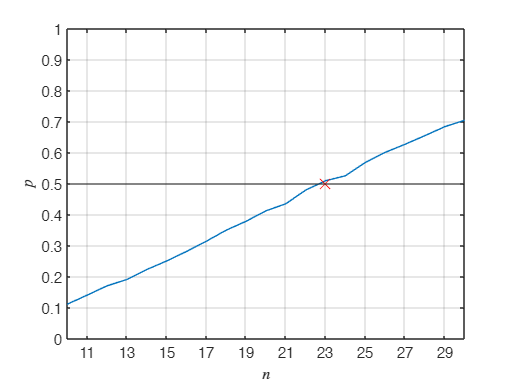

plot(ns, p)
hold on;
plot(intersection(1), intersection(2), 'red', Marker='x', MarkerSize=10)
yline(0.5)
xticks(1:2:n_max)
xlabel('$n$', 'Interpreter','latex')
ylabel('$p$', 'Interpreter','latex')
grid("on")
xlim([10,30])
ylim([0,1])
hold off;